assert(endsWith(pwd, "non-ferromagnetic metal plate with hole in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;

Coil_pos = [-10e-3, 0, 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos, [1,0,0], deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 20;
Sensor.side_length = 1e-3;

Sensor_pos = [
    linspace(-30e-3,30e-3,Sensor.num); 
    0      * ones(1,Sensor.num); 
    1.5e-3 * ones(1,Sensor.num)];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos', repmat([1,0,0],Sensor.num,1), repmat([0],Sensor.num,1));
clear Sensor_pos

#### Model

vertex_file = 'plate_l72_t2_hole_d12_vertex.csv';
element_file = 'plate_l72_t2_hole_d12_element.csv';
Model = BuildModel3D('File', vertex_file, element_file, 1e-3);

build model took 0.08 seconds


clear vertex_file element_file

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 9.06 seconds


#### Solve in frequency domain

Coil.frequency_domain.current = 1; % (A)
Coil.frequency_domain.frequency = 20000; % (Hz)

[Model, Coil, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 2.95 seconds


#### Plot result

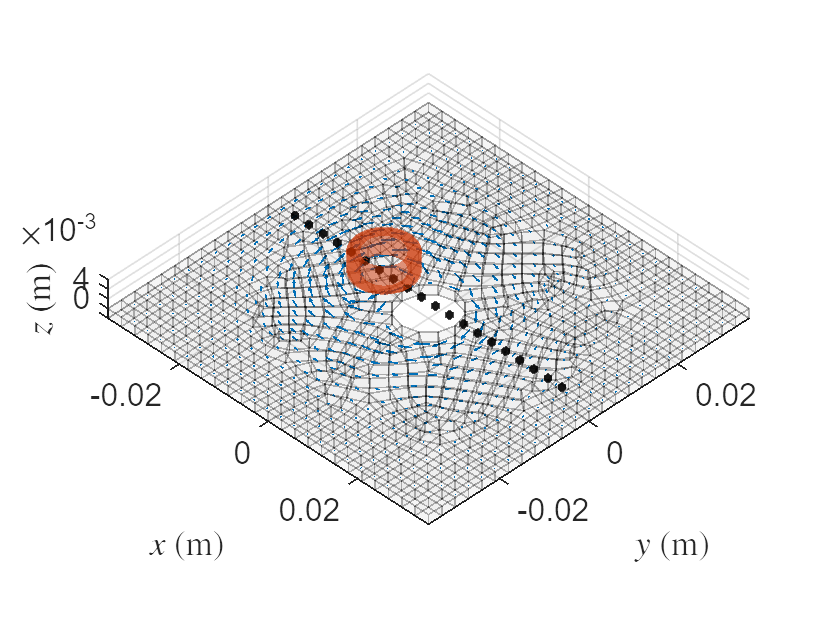

pos = Model.elms_center;
vec = real(Model.frequency_domain.J);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear pos vec

PlotWorld3D(Model, Coil, Sensor);

clf

## Compare with FEA

#### Magnetic flux density

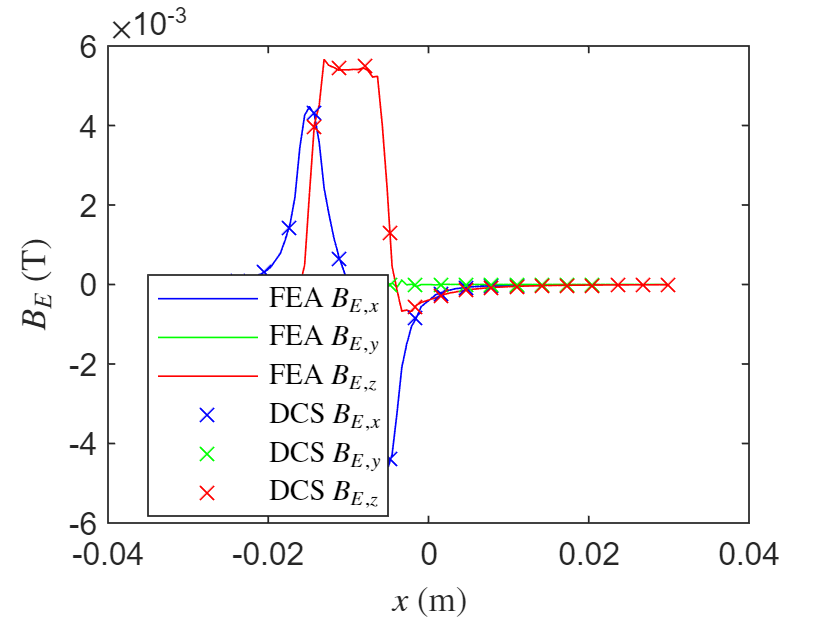

data = readmatrix('FEA_data/B_E.csv', 'CommentStyle','%');
FEA.x = data(:,1);
FEA.B_E_x = data(:,4);
FEA.B_E_y = data(:,5);
FEA.B_E_z = data(:,6);
data = readmatrix('FEA_data/B_E_plus_B_C.csv', 'CommentStyle','%');
FEA.B_C_x = data(:,4) - FEA.B_E_x;
FEA.B_C_y = data(:,5) - FEA.B_E_y;
FEA.B_C_z = data(:,6) - FEA.B_E_z;
clear data

plot(FEA.x, real(FEA.B_E_x), 'b-', 'DisplayName','FEA $B_{E,x}$'); hold on
plot(FEA.x, real(FEA.B_E_y), 'g-', 'DisplayName','FEA $B_{E,y}$');
plot(FEA.x, real(FEA.B_E_z), 'r-', 'DisplayName','FEA $B_{E,z}$');
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(1,:), 'bx', 'DisplayName','DCS $B_{E,x}$')
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(2,:), 'gx' ,'DisplayName','DCS $B_{E,y}$')
plot(Sensor.position(1,:), Sensor.frequency_domain.B_E(3,:), 'rx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

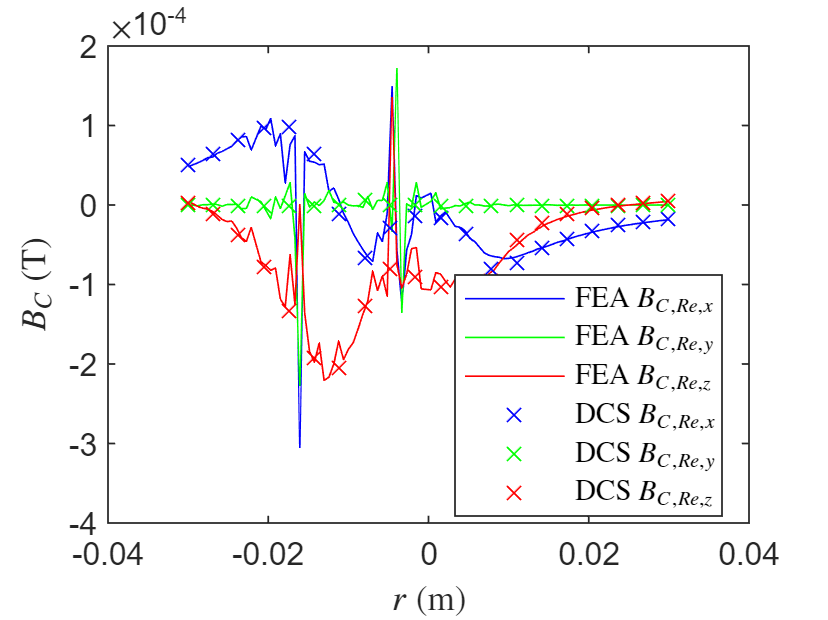

clf

plot(FEA.x, real(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Re,x}$'); hold on
plot(FEA.x, real(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Re,y}$');
plot(FEA.x, real(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Re,z}$');
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Re,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

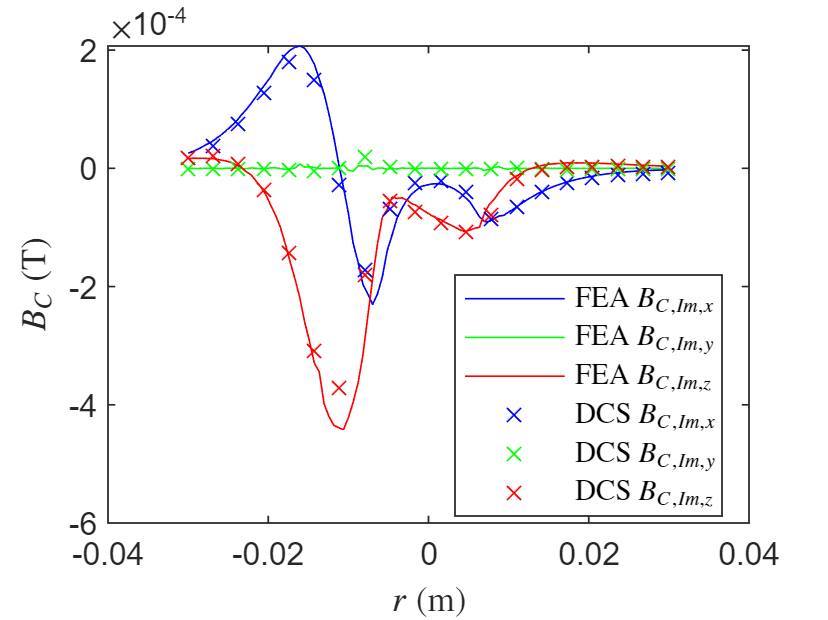

clf

plot(FEA.x, imag(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Im,x}$'); hold on
plot(FEA.x, imag(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Im,y}$');
plot(FEA.x, imag(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Im,z}$');
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Im,x}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Im,y}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf